clear all
clc
close all
t = 0:2;
q = 3;
xi = exp(1i*2*pi/q);
f = [exp(1i*2*pi/q) 1 exp(1i*4*pi/q)];
f_1 = [1 exp(1i*2*pi/q) exp(1i*4*pi/q)];
f_2 = [exp(1i*2*pi/q) exp(1i*2*pi/q) exp(1i*2*pi/q)];

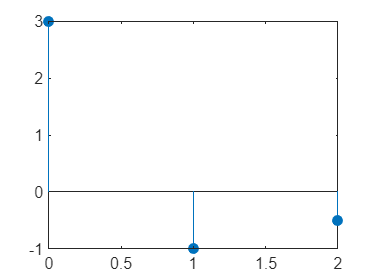

reg_shift = f;

for k = 1:3
    reg_plus_f_auto = zeros(1,3);
    for n = k:3
        reg_plus_f_auto(n)  = reg_shift(n)/f(n);
    end
    sum_f(k) = sum(reg_plus_f_auto);
    reg_shift = circshift(reg_shift,1);
end

stem(t,sum_f,"filled");

reg_shift_1 = f_1;


for k = 1:3
    reg_plus_f_auto = zeros(1,3);
    for n = k:3
        reg_plus_f_auto(n)  = reg_shift_1(n)/f_1(n);
    end
    sum_f_1(k) = sum(reg_plus_f_auto);
    reg_shift_1 = circshift(reg_shift_1,1);
end

stem(t,sum_f_1,"filled");

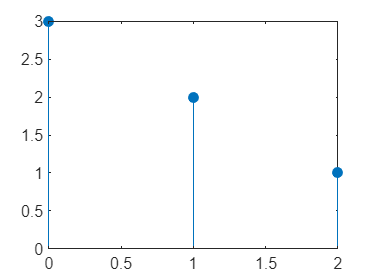

reg_shift_2 = f_2;


for k = 1:3
    reg_plus_f_auto = zeros(1,3);
    for n = k:3
        reg_plus_f_auto(n)  = reg_shift_2(n)/f_2(n);
    end
    sum_f_2(k) = sum(reg_plus_f_auto);
    reg_shift_2 = circshift(reg_shift_2,-1);
end

stem(t,sum_f_2,"filled");

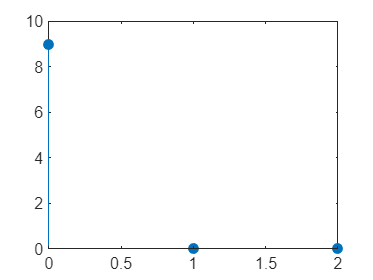

f_plus =  sum_f + sum_f_1 + sum_f_2;
stem(t,f_plus,"filled");